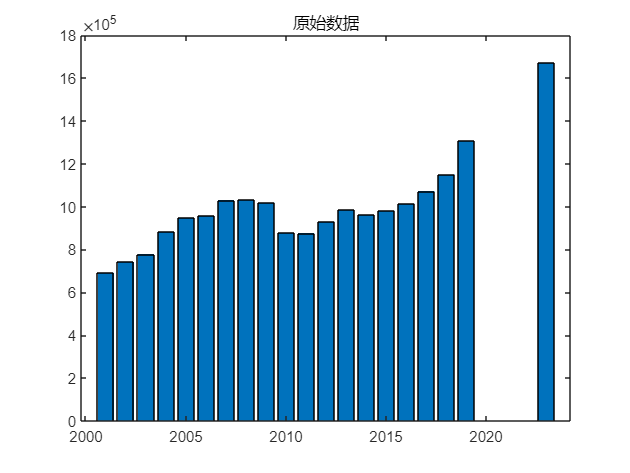

clear, clc;

% 加载数据并预处理
data = load("data.mat");  % 导入人数
data = table2array(data.data);
data(20, 2) = NaN; data(21, 2) = NaN; data(22, 2) = NaN;
bar(data(:, 1), data(:, 2));
title('原始数据');

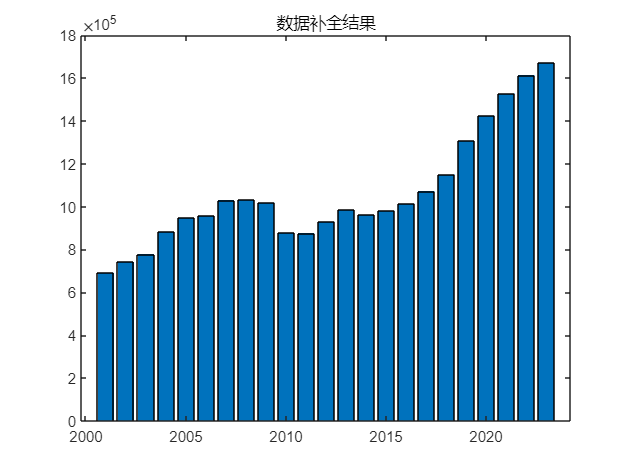


% 数据插值
chazhi_fa = char('linear', 'spline', 'pchip', 'movmean');
choice_2 = 3;
if choice_2 ~= 4
    data = fillmissing(data, strtrim(chazhi_fa(choice_2, :))); % strtrim 是为了去除字符串组的空格
else
    data = fillmissing(data, 'movmean', 10); % 窗口长度为 10 的移动均值
end
bar(data(:, 1), data(:, 2));
title('数据补全结果');

ADF检验结果:
是否拒绝原假设（序列非平稳）: 0
p值: 0.9990
KPSS检验结果:
是否拒绝原假设（序列平稳）: 0
p值: 0.0100


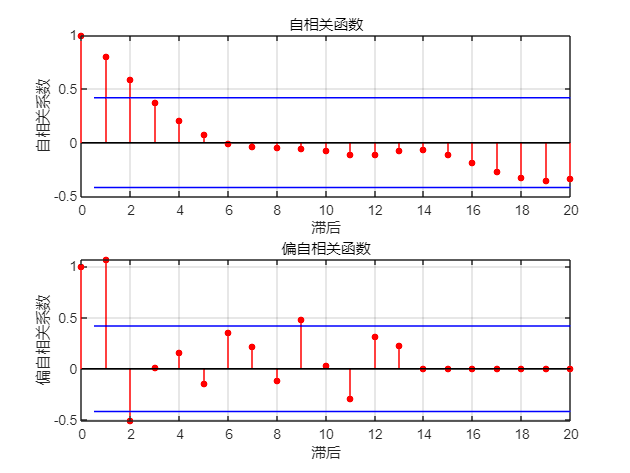

 
    ARIMA(2,1,1) Model (Gaussian Distribution):
 
                  Value       StandardError    TStatistic    PValue 
                __________    _____________    __________    _______

    Constant         23558         25963           0.9074     0.3642
    AR{1}         -0.14644       0.78973         -0.18543    0.85289
    AR{2}          0.52688       0.36695           1.4358    0.15105
    MA{1}          0.68318       0.73633          0.92781     0.3535
    Variance    3.5302e+09       0.22928       1.5397e+10          0




% 时间序列预测测试
y = data(:, 2); PreTime = 20;
forecastTest = ARIMA(PreTime, y);

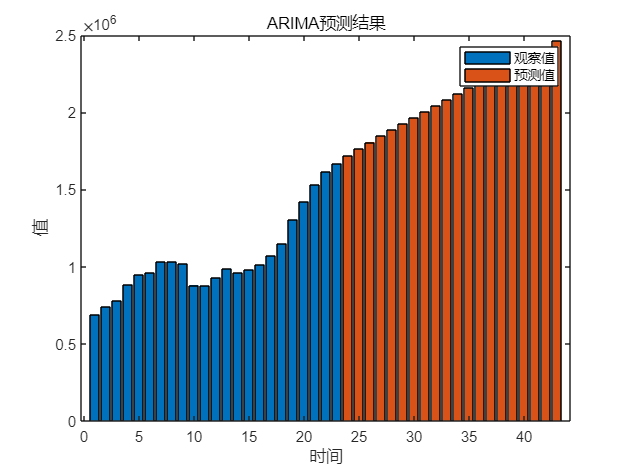

figure;
bar(y);
hold on;
time_axis = (length(y) + 1:length(y) + PreTime)';
bar(time_axis, forecastTest);
xlabel('时间');
ylabel('值');
legend('观察值', '预测值');
title('ARIMA预测结果');


% 粒子群优化参数
numParticles = 30; % 粒子数量
numIterations = 100; % 迭代次数
dim = PreTime * 2; % 维度，alpha1 和 alpha2
alpha_max = 1; % alpha1 和 alpha2 的最大值
Nmax = 1000; % Nmax 的最大值

% 初始化粒子位置和速度
positions = rand(numParticles, dim) * alpha_max;
velocities = zeros(numParticles, dim);
pBestPositions = positions;
pBestScores = inf(numParticles, 1);

% 初始化全局最佳位置
[gBestScore, gBestIndex] = min(pBestScores);
gBestPosition = pBestPositions(gBestIndex, :);

% PSO 主循环
w_max = 0.9; % 最大惯性权重
w_min = 0.4; % 最小惯性权重
c1 = 2.0; % 个体学习因子
c2 = 2.0; % 社会学习因子

for iter = 1:numIterations
    % 动态调整惯性权重
    w = w_max - (w_max - w_min) * iter / numIterations;

    for i = 1:numParticles
        % 计算适应度
        alpha_1 = positions(i, 1:PreTime);
        alpha_2 = positions(i, PreTime + 1:end);
        score = -Revenue1(Nmax, alpha_1, alpha_2, PreTime);
        
        % 更新个人最佳
        if score < pBestScores(i)
            pBestScores(i) = score;
            pBestPositions(i, :) = positions(i, :);
        end
        
        % 更新全局最佳
        if score < gBestScore
            gBestScore = score;
            gBestPosition = positions(i, :);
        end
    end
    
    % 更新速度和位置
    for i = 1:numParticles
        velocities(i, :) = w * velocities(i, :) + ...
            c1 * rand * (pBestPositions(i, :) - positions(i, :)) + ...
            c2 * rand * (gBestPosition - positions(i, :));
        positions(i, :) = positions(i, :) + velocities(i, :);
        
        % 确保位置在边界内
        positions(i, :) = max(0, min(positions(i, :), alpha_max));
    end
    
    % 输出当前迭代和最佳适应度
    fprintf('Iteration %d: Best Fitness = %.4f\n', iter, -gBestScore);
end

Iteration 1: Best Fitness = 0.0000
Iteration 2: Best Fitness = 0.0000
Iteration 3: Best Fitness = 0.0000
Iteration 4: Best Fitness = 0.0000
Iteration 5: Best Fitness = 0.0000
Iteration 6: Best Fitness = 0.0000
Iteration 7: Best Fitness = 0.0000
Iteration 8: Best Fitness = 0.0000
Iteration 9: Best Fitness = 0.0000
Iteration 10: Best Fitness = 0.0000
Iteration 11: Best Fitness = 0.0000
Iteration 12: Best Fitness = 0.0000
Iteration 13: Best Fitness = 0.0000
Iteration 14: Best Fitness = 0.0000
Iteration 15: Best Fitness = 0.0000
Iteration 16: Best Fitness = 0.0000
Iteration 17: Best Fitness = 0.0000
Iteration 18: Best Fitness = 0.0000
Iteration 19: Best Fitness = 0.0000
Iteration 20: Best Fitness = 0.0000
Iteration 21: Best Fitness = 0.0000
Iteration 22: Best Fitness = 0.0000
Iteration 23: Best Fitness = 0.0000
Iteration 24: Best Fitness = 0.0000
Iteration 25: Best Fitness = 0.0000
Iteration 26: Best Fitness = 0.0000
Iteration 27: Best Fitness = 0.0000
Iteration 28: Best Fitness = 0.0000
I


% 输出最佳个体和目标函数值
bestAlpha1 = gBestPosition(1:PreTime);
bestAlpha2 = gBestPosition(PreTime + 1:end);
bestRevenue = -gBestScore;
fprintf('Best Revenue: %.4f\n', bestRevenue);

Best Revenue: 0.0000


fprintf('Best Alpha_1: ');

Best Alpha_1: 

disp(bestAlpha1);

  列 1 至 14

    0.5038    0.9300    0.5039    0.8295    0.4504    0.1170    0.9969    0.7202    0.6690    0.5078    0.1403    0.0684    0.5324    0.7624

  列 15 至 20

    0.7269    0.6423    0.5294    0.8266    0.7588    0.9350



fprintf('Best Alpha_2: ');

Best Alpha_2: 

disp(bestAlpha2);

  列 1 至 14

    0.1982    0.0930    0.4612    0.8569    0.8954    0.5230    0.7485    0.1629    0.2905    0.9635    0.9852    0.8900    0.1080    0.8776

  列 15 至 20

    0.7750    0.1457    0.3400    0.0198    0.7960    0.5508




% 目标函数1

function R = Revenue1(Nmax, alpha_1, alpha_2, PreTime)
    % 参数
    P0 = 1; N0 = 1; S0 = 0; Ep = 1;
    Cmean = 14.4; Imean = 1; I0 = 10;
    r1 = 1/pi; r2 = 1; k1 = 0.5; k2 = 0.5;
    lambda = [0.4; 0.3; 0.3]; % 可持续性因子权重

    N = zeros(PreTime, 1); Rt = zeros(PreTime, 1);
    S = zeros(PreTime, 1); I = zeros(PreTime, 1);

    % 初始化
    N(1) = N0 * (1 + alpha_1(1) + alpha_2(1))^Ep;
    N(1) = min(Nmax, max(0, r1 * N(1) * atan(r2 * S0))); % 限制N的范围
    Rt(1) = P0 * N(1);

    % 可持续性因子，未作单位化处理; Satis为满意度函数，Rt为收入，N为人数
    I(1) = I0 + k2 * alpha_2(1) * P0 * N(1);
    S(1) = [-Cmean * N(1), -Imean * N(1) / I0, Satis(Rt(1), N(1))] * lambda;

    for t = 2:PreTime
        N(t) = N(t - 1) * ((1 + alpha_1(t) + alpha_2(t)) / (1 + alpha_1(t - 1) + alpha_2(t - 1)))^Ep;
        N(t) = min(Nmax, max(0, r1 * N(t) * atan(r2 * S(t - 1)))); % 限制N的范围
        Rt(t) = P0 * N(t);
        C = Cmean * N(t) - k1 * alpha_1(t) * P0 * N(t);
        I(t) = I(t - 1) + k2 * alpha_2(t) * P0 * N(t);
        S(t) = [-C, Imean * N(t) / I(t - 1), Satis(Rt(t), N(t))] * lambda;
    end

    % 目标函数值
    R = sum(Rt);
end

% 满意度函数（示例）
function Satis = Satis(Rt, N)
    Satis = Rt / N; % 示例满意度函数
end

% ARIMA算法
function forecastTest = ARIMA(PreTime, y)
    % 拆分数据集为训练集和测试集
    train_size = floor(0.8 * length(y));
    train_data = y;

    % 平稳性检验 - ADF检验
    [h_adf, p_adf] = adftest(y);
    fprintf('ADF检验结果:\n');
    fprintf('是否拒绝原假设（序列非平稳）: %d\n', h_adf);
    fprintf('p值: %.4f\n', p_adf);

    % 平稳性检验 - KPSS检验
    [h_kpss, p_kpss] = kpsstest(y);
    fprintf('KPSS检验结果:\n');
    fprintf('是否拒绝原假设（序列平稳）: %d\n', ~h_kpss);
    fprintf('p值: %.4f\n', p_kpss);

    % 确定参数
    y_diff = train_data;
    figure;
    subplot(2, 1, 1);
    autocorr(y_diff);
    title('自相关函数');
    xlabel('滞后');
    ylabel('自相关系数');
    subplot(2, 1, 2);
    parcorr(y_diff);
    title('偏自相关函数');
    xlabel('滞后');
    ylabel('偏自相关系数');

    % 训练ARIMA模型
    model = arima(2, 1, 1);
    model = estimate(model, y_diff);

    % 测试未来时间预测情况
    horizon = PreTime;
    [forecastTest, YMSE, forecastCI] = forecast(model, horizon, 'Y0', y_diff);
end